Si consideri il sistema di produzione mostrato in figura, costituito da un magazzino B di capacità

unitaria, seguito dall’interconnessione in serie di due macchine M1 e M2.

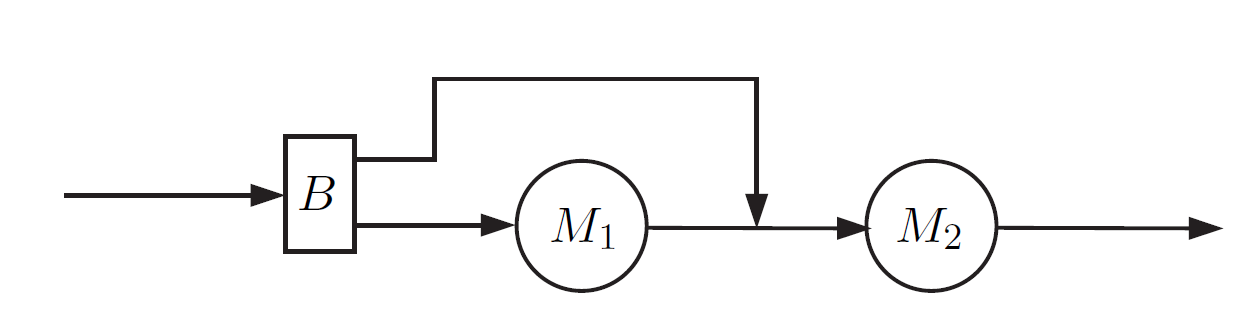

Una frazione f = 4/9 delle parti in arrivo richiede di essere processata solo in M2, mentre le altre

richiedono di essere processate in entrambe le macchine. Le parti che arrivano quando B è pieno,

vengono respinte. Se M1 termina un lavoro e M2 sta lavorando, M1 trattiene la parte lavorata (e

quindi non si rende disponibile per lavorare un’altra parte) fino a che M2 termina il lavoro in corso.

Le parti che provengono da M1 hanno priorità per accedere a M2 rispetto a quelle che aspettano

in B.

clear all % clears variables and functions from memory
close all % closes all open figures
clc % cleares the command window

m = 3; %number of events
n = 11; %number of states

ename = {'a', 'd1', 'd2'}; % original names of the events
xname = {'(0,0,0)','(0,0,1)','(0,1,0)','(2,0,1)','(0,1,1)','(1,1,0)'...
    ,'(2,1,1)','(1,1,1)','(2,B,1)','(1,B,1)','(0,B,1)'}; % original names of the states

% Definition of the logical model
model.m = m;
model.n = n;

model.p = zeros(n,n,m); % transition probabilities

model.p(:,1,1) = [0; 4/9; 5/9; 0; 0; 0; 0; 0; 0; 0; 0]; % vector n x 1
model.p(:,1,2) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];
model.p(:,1,3) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];

model.p(:,2,1) = [0; 0; 0; 4/9; 5/9; 0; 0; 0; 0; 0; 0];
model.p(:,2,2) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];
model.p(:,2,3) = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];

model.p(:,3,1) = [0; 0; 0; 0; 4/9; 5/9; 0; 0; 0; 0; 0];
model.p(:,3,2) = [0; 1; 0; 0; 0; 0; 0; 0; 0; 0; 0];
model.p(:,3,3) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];

model.p(:,4,1) = [0; 0; 0; 1; 0; 0; 0; 0; 0; 0; 0];
model.p(:,4,2) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];
model.p(:,4,3) = [0; 1; 0; 0; 0; 0; 0; 0; 0; 0; 0];

model.p(:,5,1) = [0; 0; 0; 0; 0; 0; 4/9; 5/9; 0; 0; 0];
model.p(:,5,2) = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 1];
model.p(:,5,3) = [0; 0; 1; 0; 0; 0; 0; 0; 0; 0; 0];

model.p(:,6,1) = [0; 0; 0; 0; 0; 1; 0; 0; 0; 0; 0];
model.p(:,6,2) = [0; 0; 0; 0; 1; 0; 0; 0; 0; 0; 0];
model.p(:,6,3) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];

model.p(:,7,1) = [0; 0; 0; 0; 0; 0; 1; 0; 0; 0; 0];
model.p(:,7,2) = [0; 0; 0; 0; 0; 0; 0; 0; 1; 0; 0];
model.p(:,7,3) = [0; 0; 0; 0; 1; 0; 0; 0; 0; 0; 0];

model.p(:,8,1) = [0; 0; 0; 0; 0; 0; 0; 1; 0; 0; 0];
model.p(:,8,2) = [0; 0; 0; 0; 0; 0; 0; 0; 0; 1; 0];
model.p(:,8,3) = [0; 0; 0; 0; 0; 1; 0; 0; 0; 0; 0];

model.p(:,9,1) = [0; 0; 0; 0; 0; 0; 0; 0; 1; 0; 0];
model.p(:,9,2) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];
model.p(:,9,3) = [0; 0; 0; 1; 0; 0; 0; 0; 0; 0; 0];

model.p(:,10,1) = [0; 0; 0; 0; 0; 0; 0; 0; 0; 1; 0];
model.p(:,10,2) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];
model.p(:,10,3) = [0; 0; 0; 0; 1; 0; 0; 0; 0; 0; 0];

model.p(:,11,1) = [0; 0; 0; 0; 0; 0; 0; 0; 4/9; 5/9; 0];
model.p(:,11,2) = [NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN; NaN];
model.p(:,11,3) = [0; 1; 0; 0; 0; 0; 0; 0; 0; 0; 0];

% initial state probabilities
model.p0 = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];

% Definition of the stochastic clock structure
%Parameters of exponential distributions
lambda = 0.4;
mu1 = 0.2;
mu2 = 0.2;
disp('Choice of rates: '), lambda, mu1, mu2

Choice of rates: 


lambda = 0.4000

mu1 = 0.2000

mu2 = 0.2000


F{1} = 'exprnd(1/lambda,1,L)'; % 1xL vector drawn from E(1/lambda)
F{2} = 'exprnd(1/mu1,1,L)'; % 1xL vector drawn from E(1/mu1)
F{3} = 'exprnd(1/mu2,1,L)'; % 1xL vector drawn from E(1/mu2)

Now we simulate the system we have defined above:


% SINGLE SIMULATION
disp('SINGLE SIMULATION'), disp(' ')

SINGLE SIMULATION
 


% Number of events to be simulated
kmax = 50;

% Realization of the clock sequences
L = kmax; % length of the clock sequences
V = [];
for i = 1:m
    eval([ 'V(' num2str(i) ',:) = ' F{i} ';' ]);
end

% Simulation
[E,X,T] = simprobdes(model,V);

State and event sample paths:

%{
figure,

subplot(2,1,1)% state sample path
stairs(T,X)
title('state sample path')
xlabel('time')
ylabel('state')
xlim([ min(T) max(T) ])
epsilon = 0.02;
ylim([ 1-epsilon*n (1+epsilon)*n ])
set(gca,'YTick',1:n,'YTickLabel',xname)

subplot(2,1,2), % event sample path
plot(T(2:end),E,'ro')
hold on
for i = 2:kmax+1
    plot([ T(i) T(i) ],[ 0 E(i-1) ],'r')
end
hold off
title('event sample path')
xlabel('time')
ylabel('event')
xlim([ min(T) max(T) ])
epsilon = 0.05;
ylim([ 0 (1+epsilon)*m ])
set(gca,'YTick',1:m,'YTickLabel',ename)
%}

Solution of point #2:

%Initialization of required parameters:

% Definition of matrix Q
Q = [-lambda lambda*4/9 lambda*5/9 0 0 0 0 0 0 0 0;
    mu2 -(mu2+lambda) 0 lambda*4/9 lambda*5/9 0 0 0 0 0 0;
    0 mu1 -(mu1+lambda) 0 lambda*4/9 lambda*5/9 0 0 0 0 0;
    0 mu2 0 -mu2 0 0 0 0 0 0 0;
    0 0 mu2 0 -(mu2+mu1+lambda) 0 lambda*4/9 lambda*5/9 0 0 mu1;
    0 0 0 0 mu1 -mu1 0 0 0 0 0;
    0 0 0 0 mu2 0 -(mu1+mu2) 0 mu1 0 0; 
    0 0 0 0 0 mu2 0 -(mu1+mu2) 0 mu1 0;
    0 0 0 mu2 0 0 0 0 -mu2 0 0;
    0 0 0 0 mu2 0 0 0 0 -mu2 0;
    0 mu2 0 0 0 0 0 0 lambda*4/9 lambda*5/9 -(mu2+lambda)];

% Initial state probabilities
pi_0 = model.p0;

% Analytic limit state probabilities:
% don't use (pi = pi_0' * expm(Q * 999999);), but the linear system
pi = ([Q'; ones(1,n)] \ [zeros(n,1); 1])';

disp('State limit probabilities:'), disp(pi);

State limit probabilities:
    0.0550    0.1099    0.0589    0.1835    0.1157    0.1298    0.0514    0.0643    0.0857    0.1072    0.0386



% Simulation time
Ts = 45;

%punto_2(Q, pi_0, pi, Ts)

Solution of point #3:

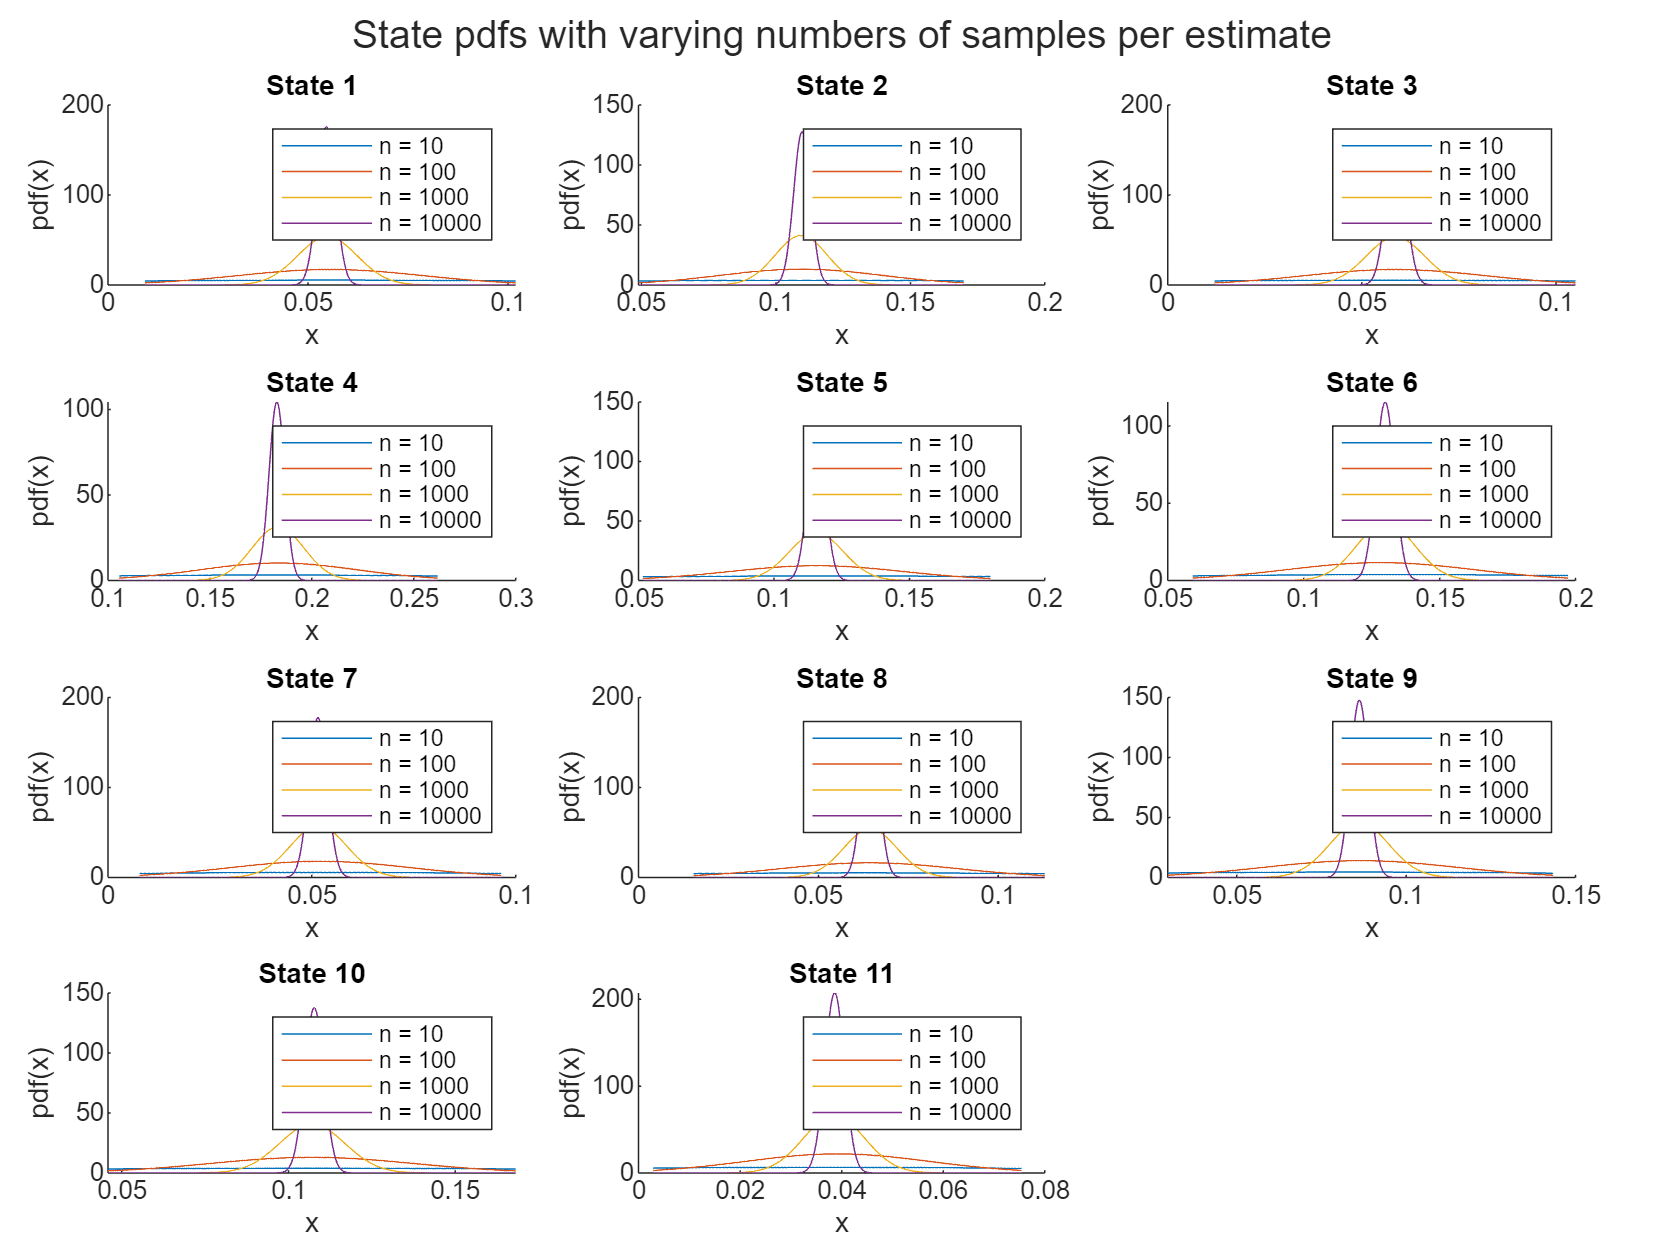

n_estimates = 1000;
samples_per_estimate_vector = [10, 100, 1000, 10000]; %tested values of samples_per_estimate
samples_per_estimate = 10;
time = 40;

%run estimation of limit state probabilities
%punto_3(n_estimates, samples_per_estimate, time, model, F, lambda, mu1, mu2)

%Show summary plot for several punto_3() executions with increasing number
%of samples per estimate
punto_3_plot()

Solution of point #4:

number_of_simulations = 10000;
%punto_4(number_of_simulations, model, F, lambda, mu1, mu2)

Solution of point #5:

kmax = 1000000; %number of simulated events
%punto_5(kmax, model, F, lambda, mu1, mu2, pi)

Solution of point #6:

kmax = 1000000;
%punto_6(kmax, model, F, lambda, mu1, mu2, pi)

Solution of point #7:

filename = 'dati_gruppo_03.mat';
%punto_7_graphs(filename, model)
num_of_estimates = 100;
num_of_simulations = 1000; %number of observations per estimate
num_of_events = 1000; %lenght of clock structure
T_max = 1000;
num_samples = 10000; %number of time samples to show on the graph
%punto_7_steady_state_check(filename, model, num_of_estimates, num_of_simulations, num_of_events, Tmax, num_samples)

Solution of point #8:

kmax = 1000000;
steady_state_time = 600;
%punto_8_a(kmax, model, filename, steady_state_time)
%punto_8_b(kmax, model, filename, steady_state_time)